## Questão 4

Projeto de ganho K para atender a um requisito de ultrapassagem percentual (%OS) e análise de dominância de polos. A função de transferência de malha aberta é dada por:


$$G(s) = \frac{K}{(s+3)(s^2+4s+5)}
$$


O requisito de projeto é uma ultrapassagem (Overshoot) de 15%. A relação entre o Overshoot (%OS) e o fator de amortecimento (ζ) é dada por:


$$\zeta = \frac{-\ln(\%OS/100)}{\sqrt{\pi^2 + \ln^2(\%OS/100)}}$$


%% Questão 4 - Definição e Cálculos
s = tf('s');
G4_base = 1 / ((s + 3) * (s^2 + 4*s + 5));

% (a) Encontrar Zeta para OS = 15%
OS_target = 15;
zeta_target = -log(OS_target/100) / sqrt(pi^2 + (log(OS_target/100))^2);

fprintf('--- Questão 4 ---\n');

--- Questão 4 ---


fprintf('Fator de amortecimento (zeta) necessário: %.4f\n', zeta_target);

Fator de amortecimento (zeta) necessário: 0.5169



% (b) Determinar o Ganho K
% Varredura para encontrar o K que resulta no zeta desejado.
k_range = 0:0.1:100;
best_K = 0;
min_error = 1e6;

for k_temp = k_range
    T_temp = feedback(k_temp * G4_base, 1);
    p_temp = pole(T_temp);
    
    % Filtrar apenas os polos complexos (parte imaginária != 0)
    complex_poles = p_temp(abs(imag(p_temp)) > 0.1);
    
    if ~isempty(complex_poles)
        [wn, z] = damp(complex_poles(1)); % Pega o zeta do primeiro par
        error = abs(z - zeta_target);
        if error < min_error
            min_error = error;
            best_K = k_temp;
        end
    end
end

% Refino do K
k_fine = (best_K-1):0.01:(best_K+1);
for k_temp = k_fine
    if k_temp <= 0, continue; end
    T_temp = feedback(k_temp * G4_base, 1);
    p_temp = pole(T_temp);
    complex_poles = p_temp(abs(imag(p_temp)) > 0.1);
    if ~isempty(complex_poles)
        [wn, z] = damp(complex_poles(1));
        if abs(z - zeta_target) < min_error
            min_error = abs(z - zeta_target);
            best_K = k_temp;
        end
    end
end

fprintf('Ganho K encontrado: %.2f\n', best_K);

Ganho K encontrado: 11.09



% (c) Função de Transferência de Malha Fechada T(s)
T4 = feedback(best_K * G4_base, 1);
disp('Função de Transferência de Malha Fechada T(s):');

Função de Transferência de Malha Fechada T(s):


printsys(T4.num{1}, T4.den{1}, 's');

 
num/den = 
 
              11.09
   --------------------------
   s^3 + 7 s^2 + 17 s + 26.09



% --- Trecho Final da Questão 4 (Substituir a plotagem) ---
% Plot do Lugar das Raízes
figure('Name', 'Questão 4 - LGR');
rlocus(G4_base); % Chama o gráfico diretamente (sem salvar em variável)
hold on;

% Sgrid sem gerar linhas extras na legenda
sgrid(zeta_target, []); 
title(['Lugar das Raízes (Linha \zeta = ' num2str(zeta_target, '%.2f') ')']);

% Marcar os polos de malha fechada
closed_loop_poles = pole(T4);
h_polos = plot(real(closed_loop_poles), imag(closed_loop_poles), 'r*', 'MarkerSize', 10);

% Truque para a Legenda: Cria uma linha "fantasma" azul para representar o LGR na legenda
h_lgr_dummy = plot(nan, nan, 'b-'); 

% Legenda usando o identificador fantasma e os polos reais
legend([h_lgr_dummy, h_polos], 'LGR', 'Polos Malha Fechada');
hold off;

% (d) Análise de Aproximação de 2ª Ordem
polos = esort(pole(T4)); % Ordena polos (parte real mais próxima de 0 primeiro)
p_dom = polos(1); % Polo complexo dominante
p_3rd = polos(3); % Terceiro polo (real)

ratio = abs(real(p_3rd) / real(p_dom));

fprintf('\n(d) Análise da Aproximação:\n');


(d) Análise da Aproximação:


fprintf('Parte Real dos Polos Dominantes: %.2f\n', real(p_dom));

Parte Real dos Polos Dominantes: -1.24


fprintf('Parte Real do Terceiro Polo: %.2f\n', real(p_3rd));

Parte Real do Terceiro Polo: -4.51


fprintf('Razão (3º polo / Dominante): %.2f\n', ratio);

Razão (3º polo / Dominante): 3.63



if ratio >= 5
    disp('CONCLUSÃO: A aproximação de 2ª ordem É VÁLIDA (Razão >= 5).');
else
    disp('CONCLUSÃO: A aproximação de 2ª ordem NÃO É precisa (Razão < 5).');
    disp('O terceiro polo está muito próximo dos dominantes e afetará a resposta.');
end

CONCLUSÃO: A aproximação de 2ª ordem NÃO É precisa (Razão < 5).


O terceiro polo está muito próximo dos dominantes e afetará a resposta.


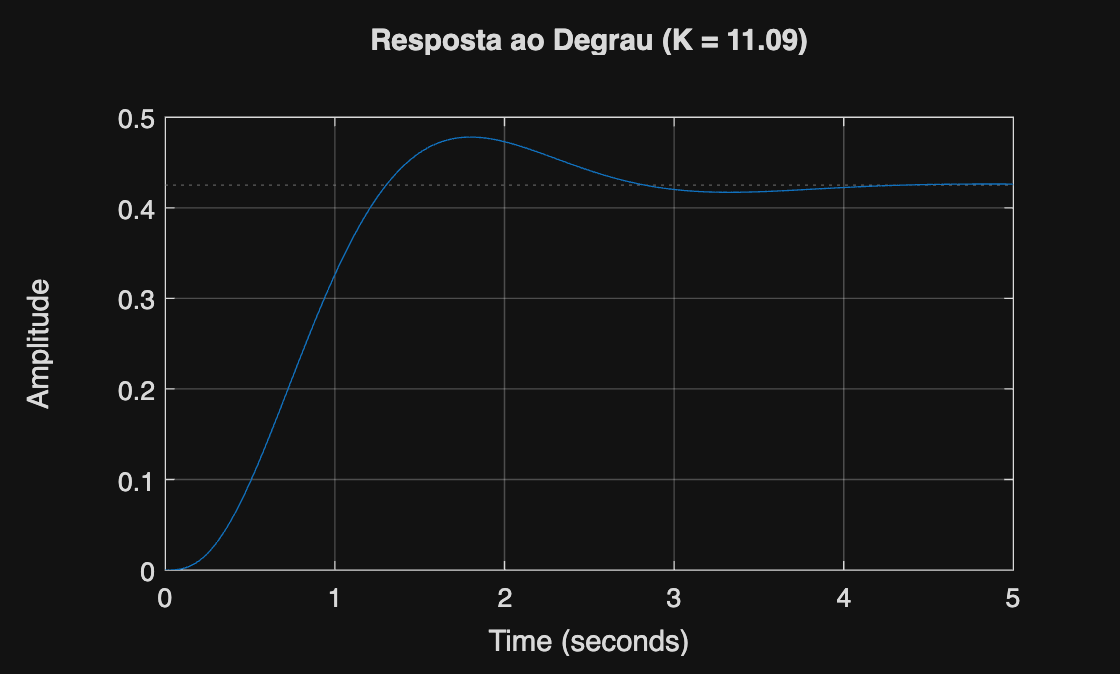


% Plot Step para confirmação visual
figure('Name', 'Questão 4 - Resposta ao Degrau');
step(T4);
title(['Resposta ao Degrau (K = ' num2str(best_K) ')']);
grid on;

Questão 5

Projeto de Controlador usando a Condição de Fase (Geometria do Lugar das Raízes). Deseja-se que o ponto sd�=−2+j2pertença ao lugar das raízes. O sistema em malha aberta é:


$$L(s) = \frac{K(Ts+1)}{s(s+2)}$$


Pela condição de ângulo:


$$\sum \angle \text{Zeros} - \sum \angle \text{Polos} = -180^{\circ}(2k+1)$$



$$\angle(s_d + 1/T) - [\angle(s_d) + \angle(s_d + 2)] = -180^{\circ}
$$


Calcularemos a deficiência angular para encontrar a posição do zero (definido por T) e, em seguida, usaremos a condição de módulo para achar K.

%% Questão 5 - Projeto do Controlador (Corrigido)

% Parâmetros do projeto
sd = -2 + 2j; % Polo desejado
p1 = 0;       % Polo da planta
p2 = -2;      % Polo da planta

% 1. Cálculo do Ângulo (Fase)
% Soma dos ângulos dos polos da planta até o ponto sd
angle_poles = rad2deg(angle(sd - p1)) + rad2deg(angle(sd - p2));
% Deficiência angular: Quanto falta para -180?
% theta_z - angle_poles = -180  => theta_z = angle_poles - 180
theta_zero = angle_poles - 180;

fprintf('--- Questão 5 ---\n');

--- Questão 5 ---


fprintf('Ângulo dos polos: %.2f graus\n', angle_poles);

Ângulo dos polos: 225.00 graus


fprintf('Ângulo necessário do Zero: %.2f graus\n', theta_zero);

Ângulo necessário do Zero: 45.00 graus



% 2. Encontrar T (Posição do Zero)
% Geometria: tan(theta_zero) = Imag(sd) / (Real(sd) - z_pos)
% z_pos = Real(sd) - Imag(sd) / tan(theta)
z_pos = real(sd) - imag(sd) / tan(deg2rad(theta_zero));

% O zero é -1/T => T = -1/z_pos
T_calc = -1 / z_pos;

fprintf('Posição do Zero: %.2f\n', z_pos);

Posição do Zero: -4.00


fprintf('Valor de T: %.4f\n', T_calc);

Valor de T: 0.2500



% 3. Encontrar K (Módulo)
% A condição de módulo no LGR nos dá o ganho da forma mônica: K_rl * |s+z| / |den| = 1
% O controlador é K(Ts+1) = K*T*(s + 1/T). 
% Logo, o ganho "K_rl" encontrado geometricamente é igual a K * T.

num_dist = abs(sd - z_pos);       % Distância do zero até sd
den_dist = abs(sd - p1) * abs(sd - p2); % Produto das distâncias dos polos

K_rl = den_dist / num_dist; % Ganho do LGR (para o formato s+z)

% Recuperando o K do controlador: K = K_rl / T
K_final = K_rl / T_calc;

fprintf('Ganho do LGR (K_rl): %.2f\n', K_rl);

Ganho do LGR (K_rl): 2.00


fprintf('Valor do Ganho K (Controlador): %.2f\n', K_final);

Valor do Ganho K (Controlador): 8.00



% --- Validação ---
% Montando o sistema com os valores calculados
Controlador = K_final * tf([T_calc 1], 1); % K(Ts+1)
Planta = tf(1, [1 2 0]);                   % 1 / s(s+2)
MalhaAberta = Controlador * Planta;
MalhaFechada = feedback(MalhaAberta, 1);

disp('Polos de malha fechada obtidos (Devem ser -2 +/- 2i):');

Polos de malha fechada obtidos (Devem ser -2 +/- 2i):


disp(pole(MalhaFechada));

  -2.0000 + 2.0000i
  -2.0000 - 2.0000i



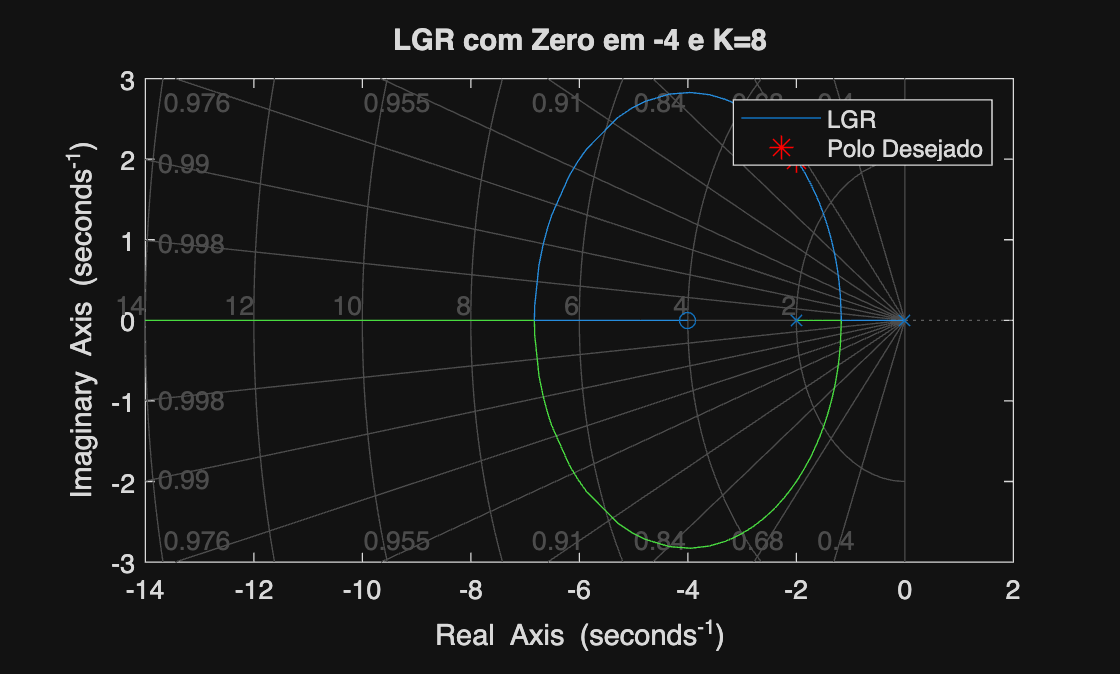


% Plot de validação
figure('Name', 'Questão 5 - Validação');
rlocus(MalhaAberta);
hold on;
plot(real(sd), imag(sd), 'r*', 'MarkerSize', 10);
title(['LGR com Zero em ' num2str(z_pos) ' e K=' num2str(K_final)]);
legend('LGR', 'Polo Desejado');
sgrid;
hold off;